# Deep learning for classification on the MNIST dataset

## Prepare the dataset

In this example, we will perform image classification using deep learning (from scratch) on the MNIST dataset. The MNIST dataset is a set of handwritten digits categorized 0-9 and is available at [http://yann.lecun.com/exdb/mnist/.](http://yann.lecun.com/exdb/mnist/.)

clear
addpath(genpath(pwd))

The following line will download (if necessary) and prepare the dataset to use in MATLAB.

[imgDataTrain, labelsTrain, imgDataTest, labelsTest] = prepareData;

Preparing MNIST data...
MNIST data preparation complete.


## Let's look at a few of the images

We will pick a random sampling of the images to take a closer look. Run this section a few times to see different picture montages. "viewDigitMontage" is a custom function found in the "03-HelperFunctions" folder.

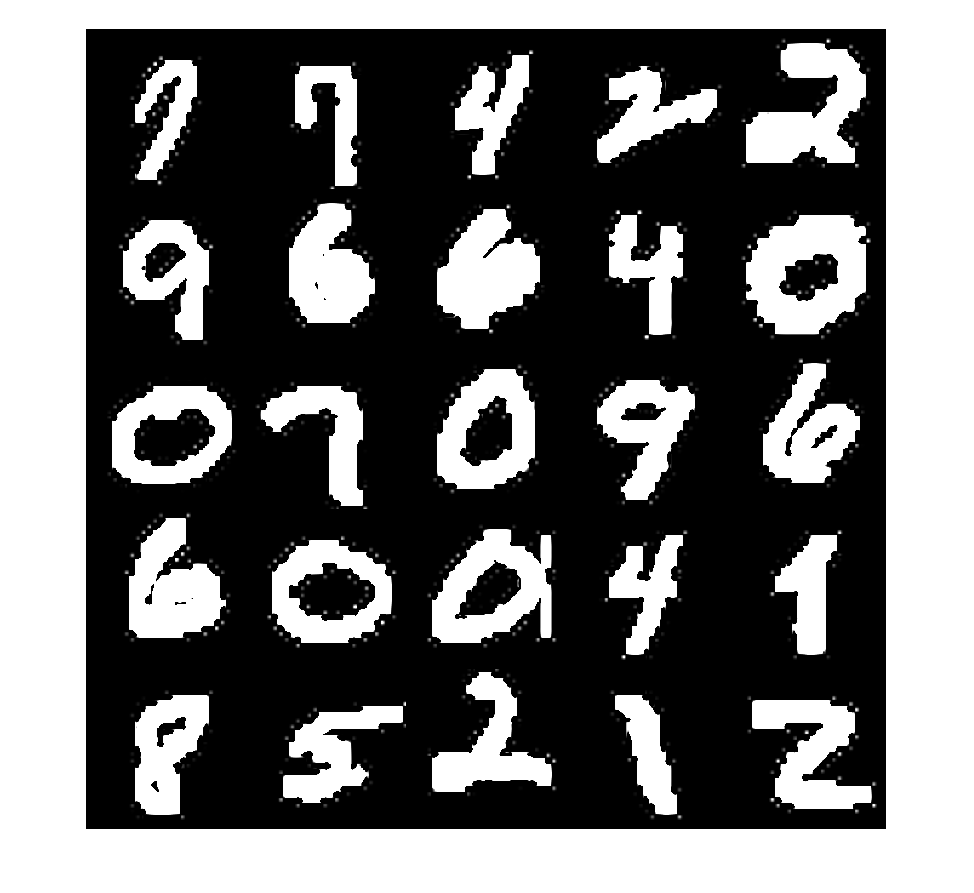

viewDigitMontage(labelsTrain, imgDataTrain)

## How do we classify a digit?

We'll start with the end goal first, and use a model already trained to classify images with MNIST, so we can see what we're trying to achieve.

load MNISTModel

**Note: **You can execute this section of the script multiple times and get a random classification image each time.

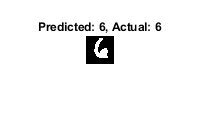

% Predict the class of an image
randIndx = randi(numel(labelsTest));
img = imgDataTest(:,:,1,randIndx);
actualLabel = labelsTest(randIndx);

predictedLabel = classify(net,img);
imshow(img);
title(['Predicted: ' char(predictedLabel) ', Actual: ' char(actualLabel)])

## Prepare the CNN

We found an example of a convolutional neural network (CNN) in the documentation. One of the simplest possible convnets, it contains one convolutional layer, one ReLU, one pooling layer, and one fully connected layer. Let's utilize it as our first attempt at classifying these images.

layers = [  imageInputLayer([28 28 1])
            convolution2dLayer(5,20)
            reluLayer
            maxPooling2dLayer(2, 'Stride', 2)
            fullyConnectedLayer(10)
            softmaxLayer
            classificationLayer   ]

layers =   7x1 Layer array with layers:

     1   ''   Image Input             28x28x1 images with 'zerocenter' normalization
     2   ''   Convolution             20 5x5 convolutions with stride [1  1] and padding [0  0  0  0]
     3   ''   ReLU                    ReLU
     4   ''   Max Pooling             2x2 max pooling with stride [2  2] and padding [0  0  0  0]
     5   ''   Fully Connected         10 fully connected layer
     6   ''   Softmax                 softmax
     7   ''   Classification Output   crossentropyex

## Deep Network Designer

You can also create networks using the Deep Network Designer. This app provides a drag-and-drop interface, which lets you define layer architecture, layer parameters, and layer connections. After creating a network, you can check it for errors then export it to the workspace. Try to create the network we defined above!

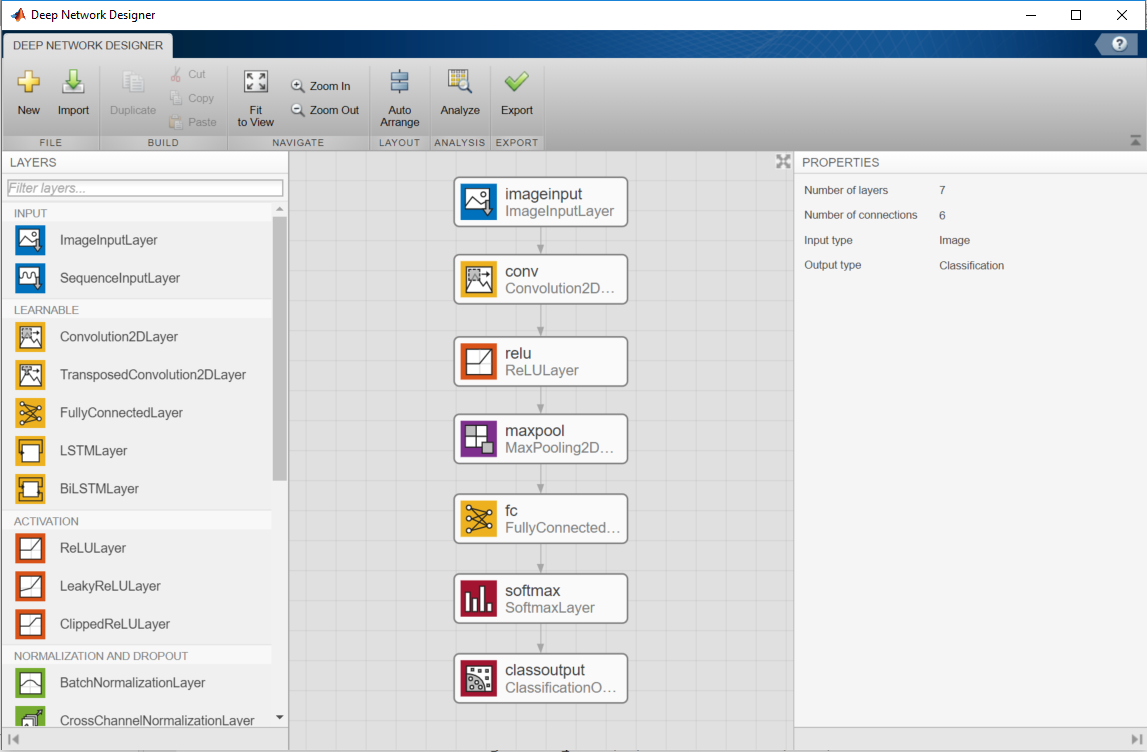

% deepNetworkDesigner 

## Attempt 1: Set training options and train the network

Let's use default values and try training this network. 

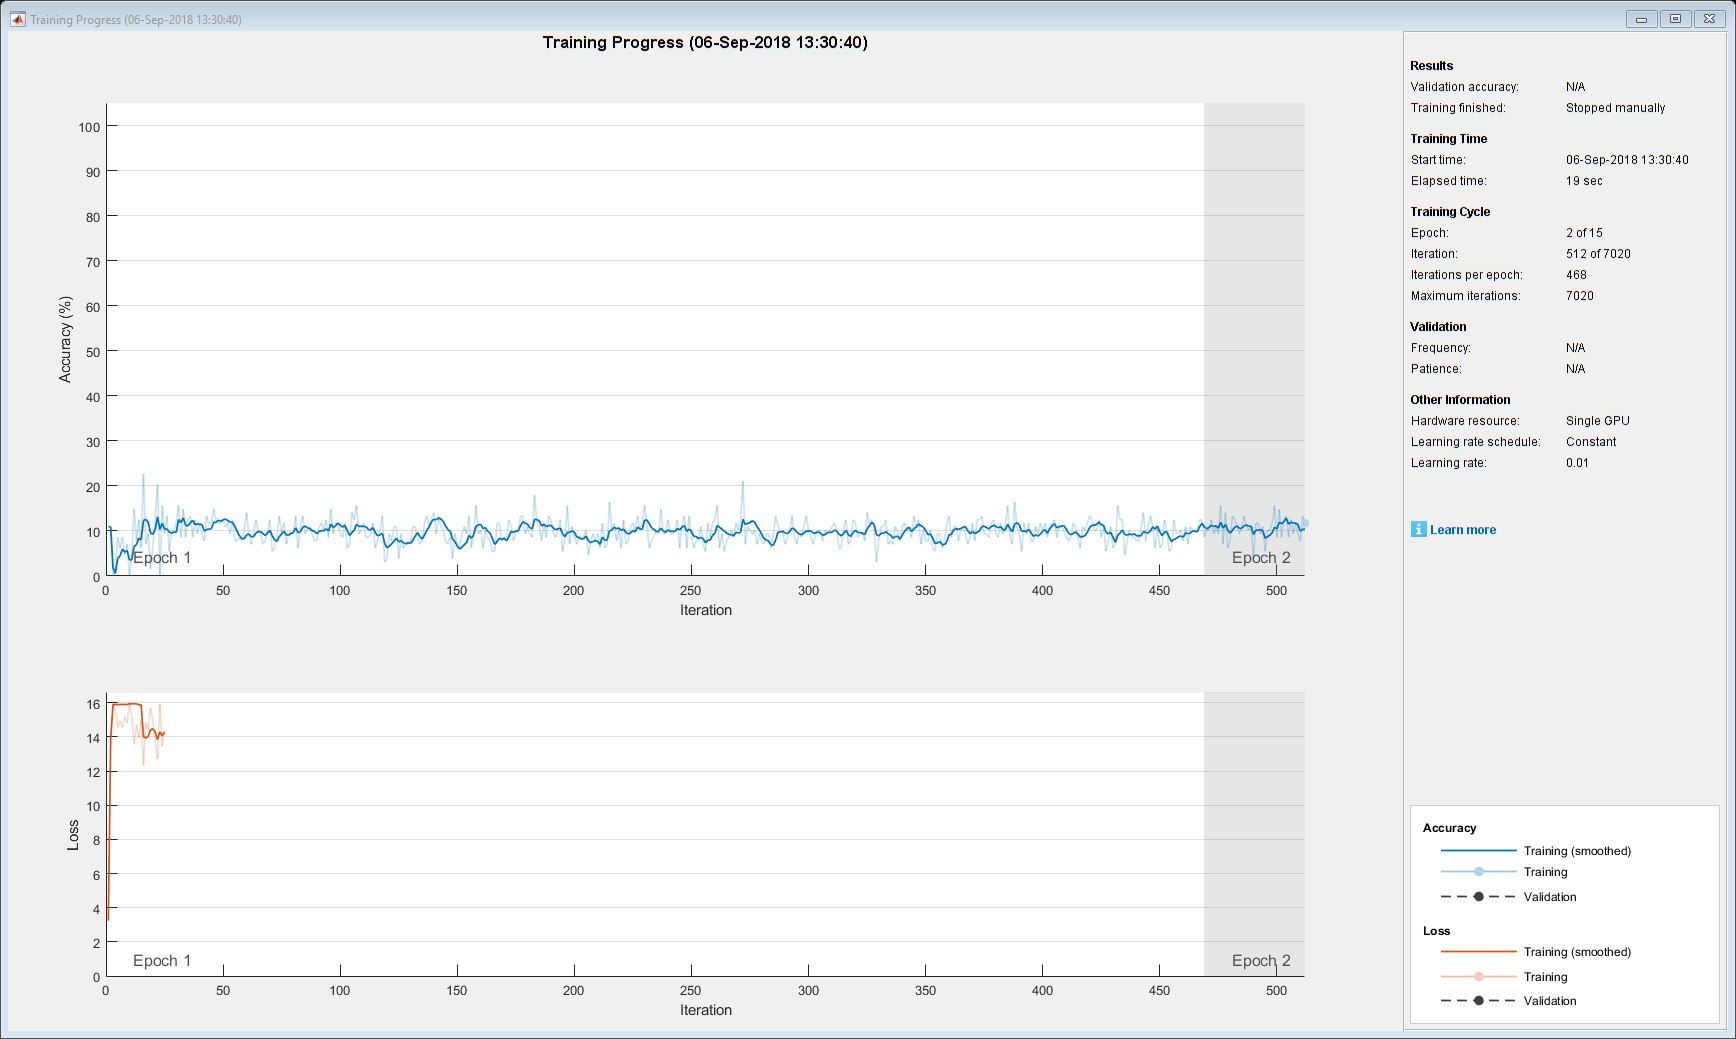

Training on single GPU.


Initializing image normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:01 |       10.94% |       3.2426 |          0.0100 |
|       1 |          50 |       00:00:03 |       12.50% |          NaN |          0.0100 |
|       1 |         100 |       00:00:05 |        9.38% |          NaN |          0.0100 |
|       1 |         150 |       00:00:06 |        7.03% |          NaN |          0.0100 |
|       1 |         200 |       00:00:08 |        8.59% |          NaN |          0.0100 |
|       1 |         250 |       00:00:10 |        8.59% |          NaN |          0.0100 |
|       1 |         300 |       00:00:12 |       10.16% 

options = trainingOptions( 'sgdm',...
    'Plots', 'training-progress',...
    'MaxEpochs',10);

net = trainNetwork(imgDataTrain, labelsTrain, layers, options);

## Attempt 2: Change the learning rate

That didn't work too well. Let's try changing one of the main parameters that affects neural network training: the **learning rate.**

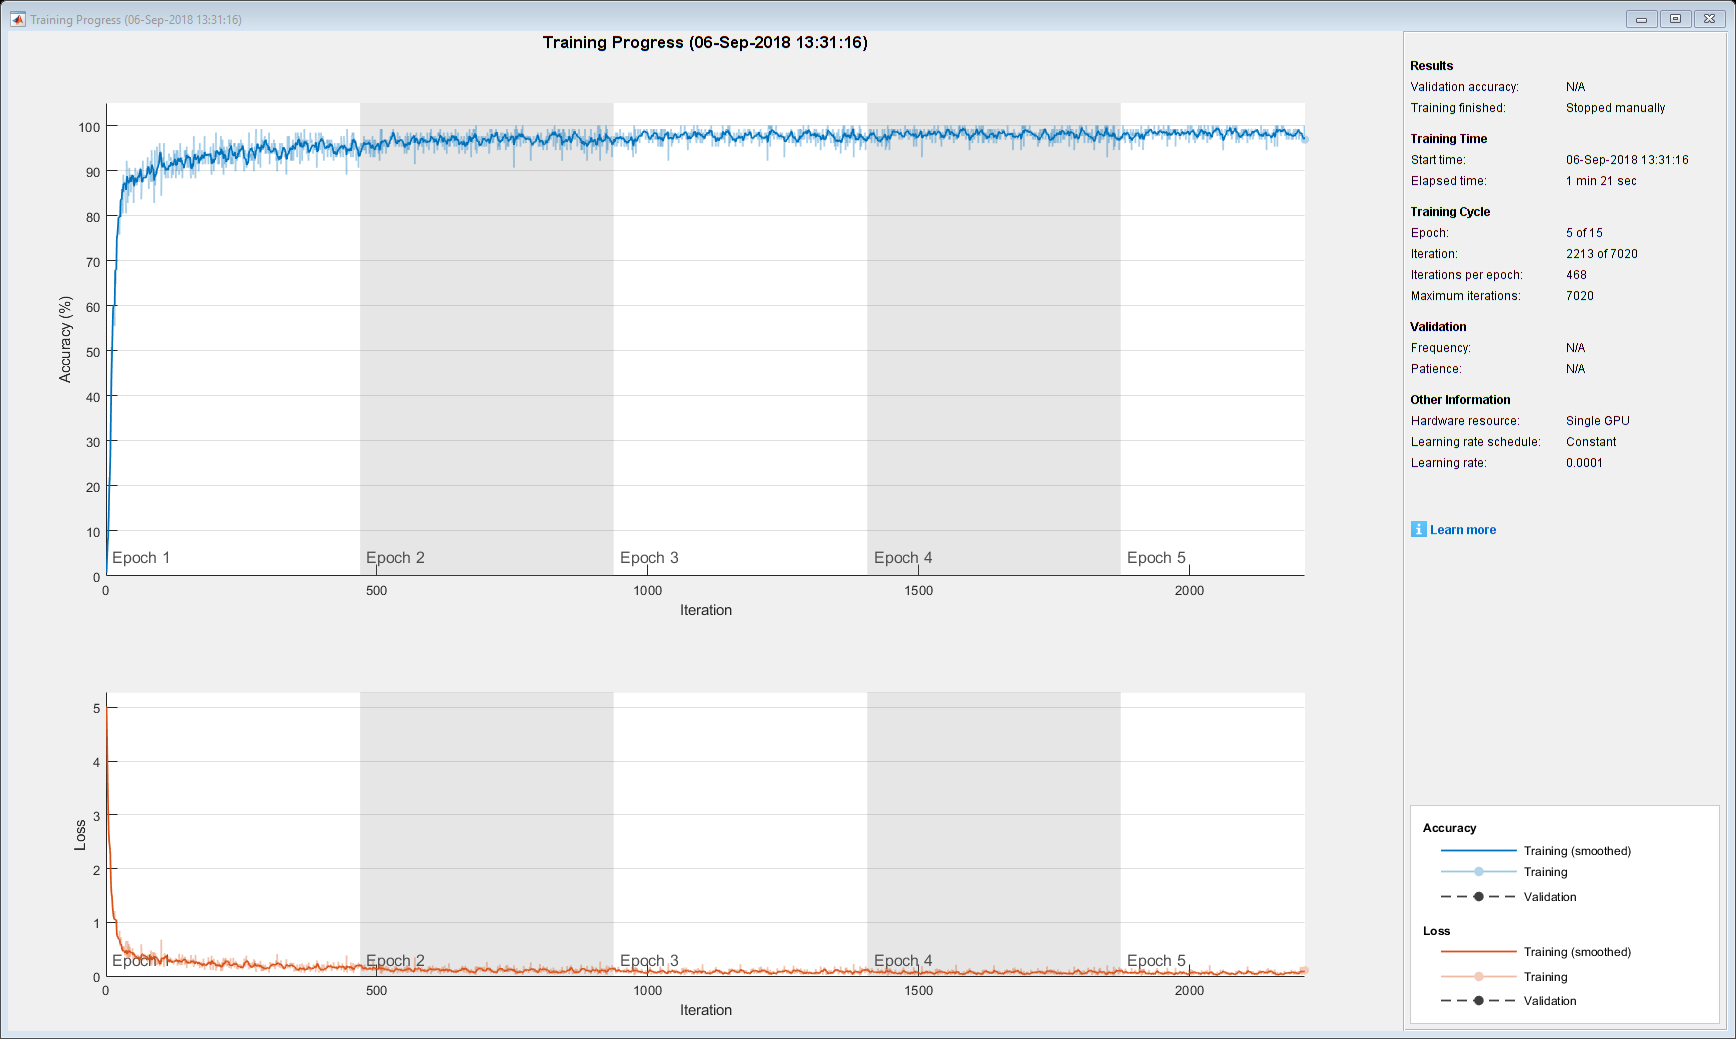

Training on single GPU.


Initializing image normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:01 |        0.78% |       5.0161 |      1.0000e-04 |
|       1 |          50 |       00:00:03 |       88.28% |       0.3062 |      1.0000e-04 |
|       1 |         100 |       00:00:05 |       92.19% |       0.2768 |      1.0000e-04 |
|       1 |         150 |       00:00:07 |       90.63% |       0.3044 |      1.0000e-04 |
|       1 |         200 |       00:00:08 |       94.53% |       0.2589 |      1.0000e-04 |
|       1 |         250 |       00:00:10 |       94.53% |       0.2127 |      1.0000e-04 |
|       1 |         300 |       00:00:12 |       93.75% 

options = trainingOptions('sgdm',...
    'Plots', 'training-progress',...
    'MaxEpochs',10,...
    'InitialLearnRate', 0.0001);

net = trainNetwork(imgDataTrain, labelsTrain, layers, options);

## Attempt 3: Change the network architecture

Sometimes, it's not the learning rate that needs changing. Other factors about the model can affect the training as well. Here, instead of playing with hyperparameters such as the learning rate, we can use a more sophisticated CNN in the first place. This one has multiple convolution layers, as well as **batch normalization** layers, which improve the quality and convergence rate of the training.

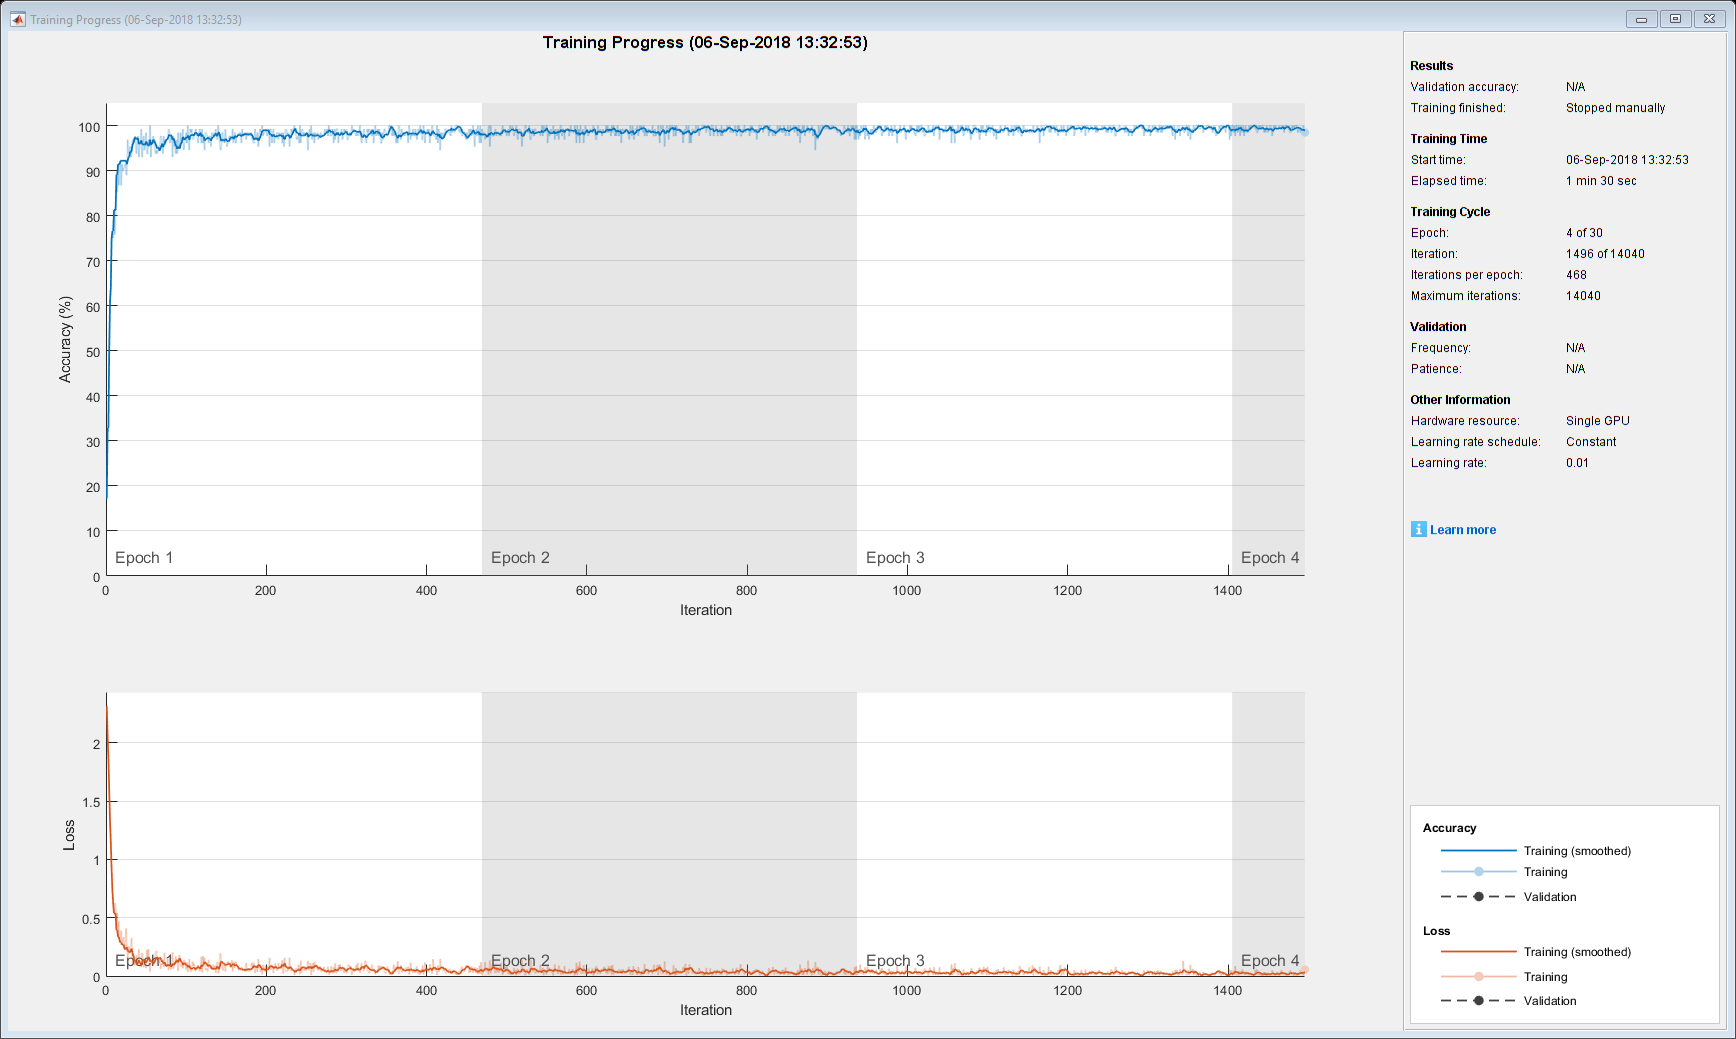

Training on single GPU.


Initializing image normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:01 |       17.19% |       2.3120 |          0.0100 |
|       1 |          50 |       00:00:04 |       98.44% |       0.0682 |          0.0100 |
|       1 |         100 |       00:00:07 |       98.44% |       0.0579 |          0.0100 |
|       1 |         150 |       00:00:10 |       96.88% |       0.0994 |          0.0100 |
|       1 |         200 |       00:00:13 |       99.22% |       0.0275 |          0.0100 |
|       1 |         250 |       00:00:16 |       98.44% |       0.0594 |          0.0100 |
|       1 |         300 |       00:00:19 |       99.22% 

layers = [
    imageInputLayer([28 28])

    convolution2dLayer(3,16,'Padding',1)
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(2,'Stride',2)

    convolution2dLayer(3,32,'Padding',1)
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(2,'Stride',2)

    convolution2dLayer(3,64,'Padding',1)
    batchNormalizationLayer
    reluLayer

    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer];

options = trainingOptions('sgdm',...
    'Plots', 'training-progress');

net = trainNetwork(imgDataTrain, labelsTrain, layers, options);

## Classify the test data set

We have a separate set of images in the MNIST dataset set aside specifically for testing. Let's use the test data to test the accuracy of the model we just trained.

predLabelsTest = classify(net,imgDataTest);

testAccuracy = sum(predLabelsTest == labelsTest) / numel(labelsTest)

testAccuracy = 0.9902

## Try to classify our own images

Let's try to classify the digits in the "03 - Handwritten Digits" folder

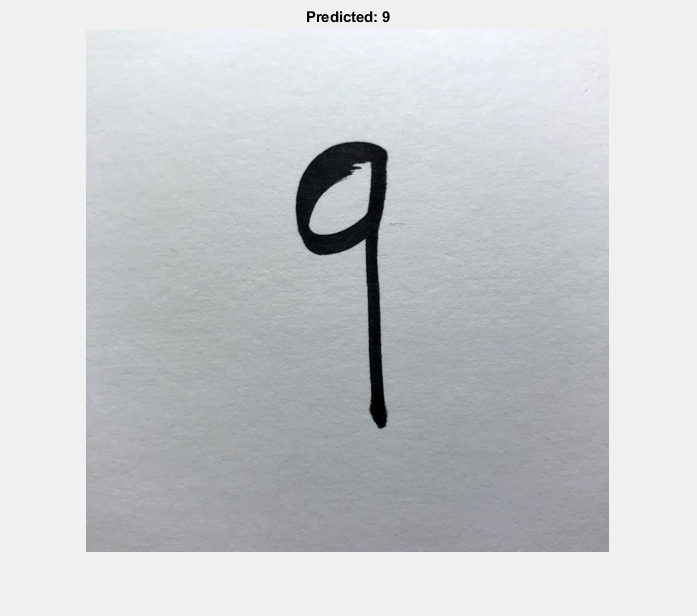

imgPath = fullfile('03-HandwrittenDigits');
ids = imageDatastore(imgPath);

f = figure; 
f.Visible = 'on';

while hasdata(ids)
    
    iOriginal = read(ids);
    iFinal = preprocessImage(iOriginal); 
    
    prediction = classify(net,iFinal);
    
    imshow(imresize(iOriginal,0.5));
    title(['Predicted: ' char(prediction)]);
    
    pause(1)
         
end

## Why change learning rate? (optional aside)

The following app dives into a brief explanation of how the **learning rate **parameter affects training in machine learning algorithms.

gradientDescentVisualization 

*Copyright 2019 The MathWorks, Inc.*